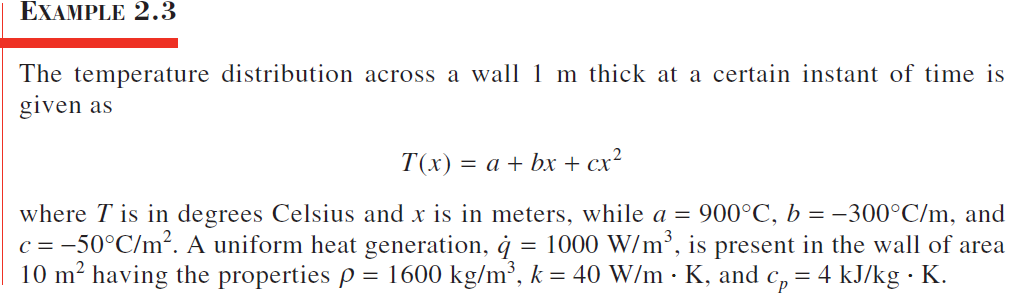

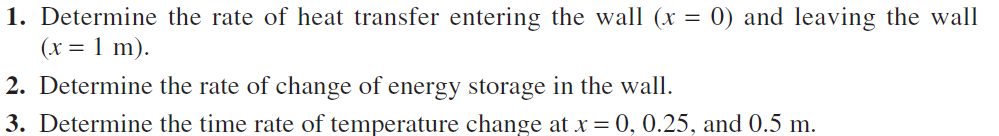

syms x
a = 900;
b = -300;
c = -50;
q_t = 1000; %W/m^3
A = 10; %m^2
rho = 1600; % kg/m^3
k = 40; %W/m * K
c_p = 4; % kJ/kg * K

T = a + b*x + c*x^2 

$$T = -50\,x^{2}-300\,x+900$$


dTdt = diff(T)

$$dTdt = -100\,x-300$$

dTdt_num =matlabFunction(dTdt)

dTdt_num = function_handle with value:
    @(x)x.*-1.0e+2-3.0e+2


% dTdt_num(0)
% dTdt_num(1)

q_in = -k*A*dTdt %fouires formel

$$q\_in = 40000\,x+120000$$


q_left = subs(q_in, x,0)

$$q\_left = 120000$$

q_right = subs(q_in, x,1)

$$q\_right = 160000$$

2 - opstiller energi balance

E_in = q_left;
E_out = q_right;
E_g = q_t * A * 1;

E_st = E_in + E_g - E_out 

$$E\_st = -30000$$